f = load('/home/juanpis/DSP/wavelet/ECG2.txt');
[c,l] =wavedec (f,3,'db2');%Descomposicion de la seña en 3 niveeles

approx = appcoef(c,l,'db2'); %coeficientes de aprox (F.B)
[cd1,cd2,cd3] = detcoef (c,l,[1,2,3]); % Coeficiente de detalle (FA)

subplot (5,1,1)

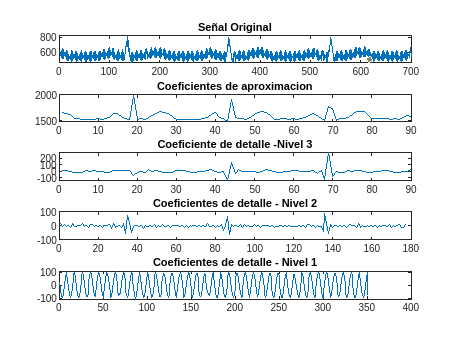

plot(f)
title('Señal Original')


subplot (5,1,2)
plot(approx)
title('Coeficientes de aproximacion')


subplot (5,1,3)
plot(cd3)
title('Coeficiente de detalle -Nivel 3')

subplot (5,1,4)
plot(cd2)
title('Coeficientes de detalle - Nivel 2')


subplot (5,1,5)
plot(cd1)
title('Coeficientes de detalle - Nivel 1')